## initialize environment

defaultDir = 'M:\Projects and Analysis\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd('Figure 3 - Calcium Imaging');

load('.\Data\Control_MRS\Broad ROIS\Ca2_MRS_data.mat');

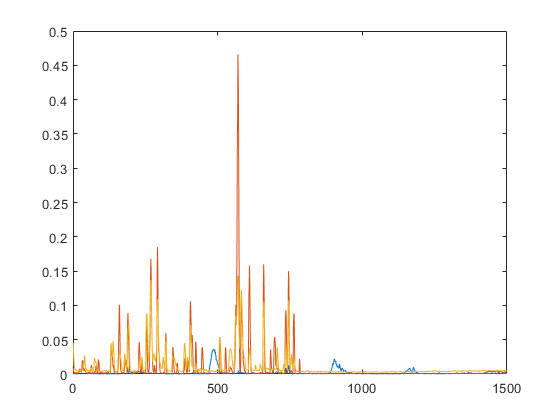

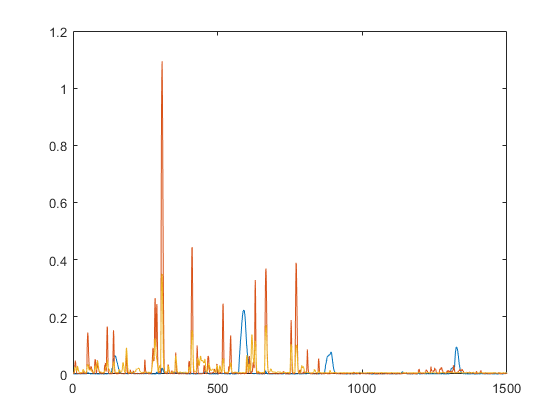

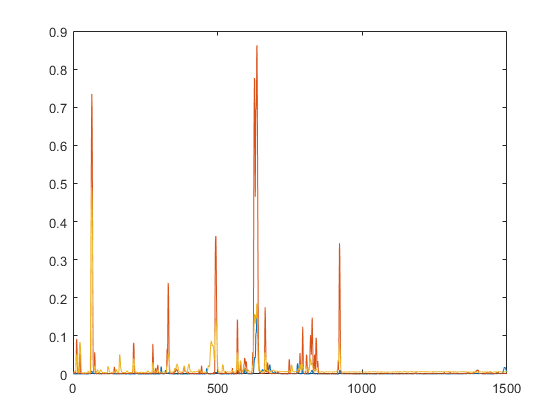

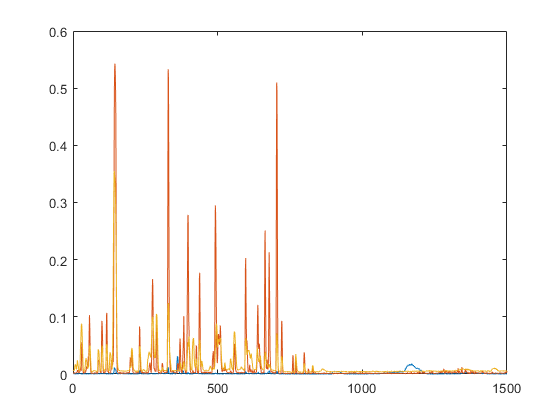

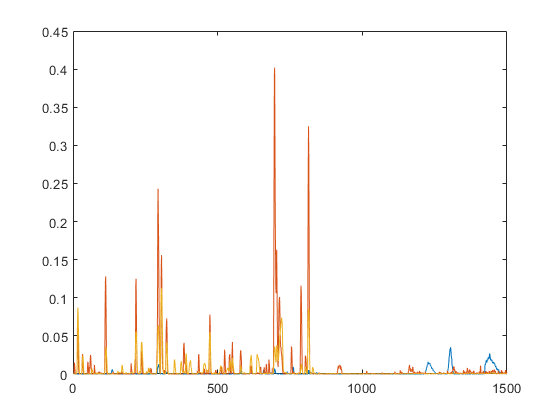

%cycle through plots
for i=1:5
    data = Ca2_MRS_data{i,2};
    figure;
    plot(data);
end

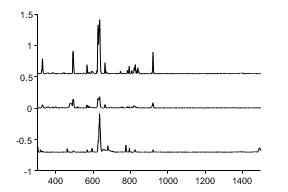

%use number 3 for figure
data = Ca2_MRS_data{3,2};
figure;
plot([data(:,1)*4]-.7,'Color','k');
hold on;
plot(data(:,2)+0.55,'Color','k');
plot(data(:,3),'Color','k');
xlim([300 inf]);
figQuality(gcf,gca,[3 2]);
export_fig('.\EPS Panels\BroadRois_Exemplar.eps','-eps');

Ca2_MRS_data_w = zeros(1,9);
Ca2_MRS_data_w = Ca2_MRS_data;
time = [1:1:1500]';
time(:,2) = time(:);
time(:,3)= time(:,1);

for i=1:size(Ca2_MRS_data,1)
    signal = Ca2_MRS_data_w{i,2};
    signal = smooth(signal,3);
    signal = reshape(signal,([1500 3]));
    signal = msbackadj(time,signal);
    Ca2_MRS_data_w{i,3} = signal;
    %SGN *note: maxPeakWidth used to elimiante any large cell death events
    %from analysis
    [pks,locs] = findpeaks(signal(:,1),'MaxPeakWidth',6,'MinPeakProminence',.001);
    pks = pks(locs < 900);
    locs = locs(locs < 900);
    Ca2_MRS_data_w{i,4}=[pks,locs];
    Ca2_MRS_data_w{i,5}=size(locs(locs<=600),1);
    Ca2_MRS_data_w{i,6}=size(locs(locs>=900),1);
    
    %IHC and ISCs
    [pks,locs] = findpeaks(signal(:,2),'MinPeakProminence',.02);
    Ca2_MRS_data_w{i,7}=[pks,locs];
    Ca2_MRS_data_w{i,8}=size(locs(locs<=600),1);
    Ca2_MRS_data_w{i,9}=size(locs(locs>=900),1);
    
    [pks,locs] = findpeaks(signal(:,3),'MinPeakProminence',.02,'Annotate','extents');
    Ca2_MRS_data_w{i,10}=[pks,locs];
    Ca2_MRS_data_w{i,11}=size(locs(locs<=600),1);
    Ca2_MRS_data_w{i,12}=size(locs(locs>=900),1);
end


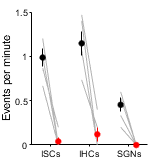

%%plot figure

offset = 0.2;
labels = [1 1 1 1 1 2 2 2 2 2 3 3 3 3 3];
con_activity = [[Ca2_MRS_data_w{:,11}] [Ca2_MRS_data_w{:,8}] [Ca2_MRS_data_w{:,5}]]/15;
MRS_activity = [[Ca2_MRS_data_w{:,12}] [Ca2_MRS_data_w{:,9}] [Ca2_MRS_data_w{:,6}]]/5;
mean_con = [mean(con_activity(1:5)) mean(con_activity(6:10)) mean(con_activity(11:15))];
mean_MRS = [mean(MRS_activity(1:5)) mean(MRS_activity(6:10)) mean(MRS_activity(11:15))];
sterr_con = [sterr(con_activity(1:5),2) sterr(con_activity(6:10),2) sterr(con_activity(11:15),2)];
sterr_MRS = [sterr(MRS_activity(1:5),2) sterr(MRS_activity(6:10),2) sterr(MRS_activity(11:15),2)];
figure;
line([labels-offset; labels+offset],[con_activity;MRS_activity],'Color',[0.7 0.7 0.7]);
hold on;
errorbar([[1:3]-offset],mean_con,sterr_con,'Marker','.','MarkerSize',15,'CapSize',0,'Color','k','LineStyle','none');
errorbar([[1:3]+offset],mean_MRS,sterr_MRS,'Marker','.','MarkerSize',15,'CapSize',0,'Color','r','LineStyle','none');
xlim([0.5 3.5])
xticks(1:3);
xticklabels({'ISCs','IHCs','SGNs'});
ylabel('Events per minute');
figQuality(gcf,gca,[1.7 1.7]);
export_fig('.\EPS Panels\BroadROIActivity.eps','-eps');

[h,p] = ttest([Ca2_MRS_data_w{:,5},Ca2_MRS_data_w{:,6}])

h = 1

p = 0.0250

[h,p] = ttest([Ca2_MRS_data_w{:,8},Ca2_MRS_data_w{:,9}])

h = 1

p = 0.0140

[h,p] = ttest([Ca2_MRS_data_w{:,11},Ca2_MRS_data_w{:,12}])

h = 1

p = 0.0161

h = load('.\Data\Control_MRS\IHCs\MRSIHCgroupData.mat');
cells = h.IHCgroup_w;

compare2P([cells{:,7}]',[cells{:,8}]',{'Baseline','+MRS2500'},'Corr coef',[3 2])

   2.6538e-04



ans =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


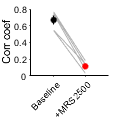

figQuality(gcf,gca,[1.25 1.25])
ylim([0 0.8])
yticks([0:0.2:0.8]);
xtickangle(45);
export_fig('.\EPS Panels\corr_coef.eps')

%%do a little more complex analysis on the corr coeffs
h = load('.\Data\Control_MRS\IHCs\MRSIHCgroupData.mat');
cells = h.IHCgroup_w;
baseline = [1 600];
MRS = [1100 1500];
for i=1:size(IHCgroup_w,1)
    IHCs = cells{i,2};
    IHCs = IHCs(:,any(IHCs));
    IHCs_baseline = IHCs(baseline(1):baseline(2),:);
    IHCs_MRS = IHCs(MRS(1):MRS(2),:);
    IHCb_shuf = IHCs_baseline(:,randperm(size(IHCs_baseline,2)));
    IHCm_shuf = IHCs_MRS(:,randperm(size(IHCs_baseline,2)));
    
    pattern = [1/4;1/4;0;1/4;1/4];
    corrb = corr(IHCs_baseline);
    convb = conv2(corrb,pattern,'same');
    corrsb = diag(convb);
    corrM = corr(IHCs_MRS);
    convM = conv2(corrM,pattern,'same');
    corrsM = diag(convM)
    corrbs = corr(IHCb_shuf);
    convbs = conv2(corrbs,pattern,'same');
    corrsbs = diag(convbs);
    corrms = corr(IHCm_shuf);
    convms = conv2(corrms,pattern,'same');
    corrsms = diag(convms);
    
    bcorr(i) = mean(corrsb);
    mcorr(i) = mean(corrsM);
    bscorr(i) = mean(corrsbs);
    mscorr(i) = mean(corrsms);
end

corrsM =     0.0928
    0.1446
    0.1086
    0.1722
    0.1442
    0.0994
    0.0886
    0.1700
    0.1031
    0.0645


corrsM =     0.0145
    0.0096
   -0.0014
   -0.0076
    0.0353
   -0.0016
    0.0567
    0.0586
    0.0930
    0.0787


corrsM =     0.0755
    0.0771
    0.0269
    0.0582
    0.0185
    0.1340
    0.0848
    0.1025
    0.1584
    0.1576


corrsM =     0.1117
    0.1698
    0.0907
    0.0790
    0.0189
    0.0793
    0.0629
    0.0641
    0.0691
    0.0949


corrsM =     0.1741
    0.1737
    0.0829
    0.0758
    0.1534
    0.1867
    0.0130
    0.0624
    0.0371
    0.0856




compare2P(bcorr',mcorr',{'Baseline','+MRS2500'},'Corr coef',[3 2])

   1.9380e-04



ans =   Figure (104) with properties:

      Number: 104
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


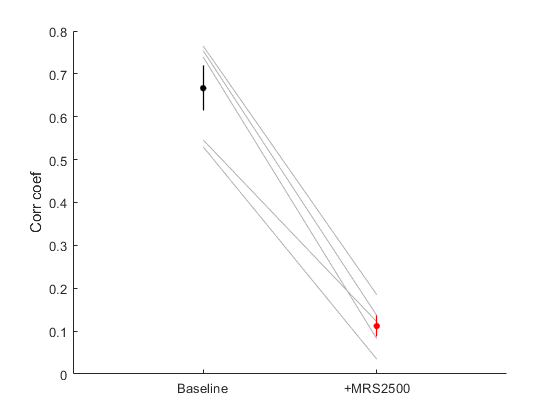

ylim([0 0.8])

compare2P(bscorr',mscorr',{'Baseline','+MRS2500'},'Corr coef',[3 2])

    0.0033



ans =   Figure (105) with properties:

      Number: 105
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


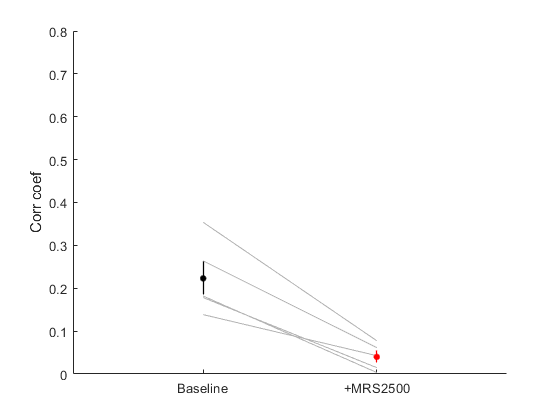

ylim([0 0.8])

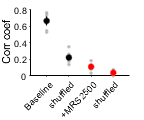

compare4P_2(bcorr', bscorr', mcorr', mscorr', {'Baseline','shuffled','+MRS2500','shuffled'}, 'Corr coef', [3 2], [20 15]);
ylim([0 0.81])
xtickangle(45)
figQuality(gcf,gca,[1.5 1.25])
export_fig('.\EPS Panels\corr_coef2.eps')

[h,p] = ttest2(mcorr,mscorr)

h = 1

p = 0.0377

[h,p] = ttest2(bcorr,mcorr)

h = 1

p = 1.2747e-05

[h,p] = ttest2(bcorr,bscorr)

h = 1

p = 1.3945e-04